## **Fourth-order ODE:**

y'''' + 4y'' + 4y = 0, y(0) = 1, y'(0) = 0, y''(0) = 0, y'''(0) = -4

**Exact solution:**

y(x) = ((x - 1) sin(sqrt(2) x))/sqrt(2) + (x + 1) cos(sqrt(2) x)

% Define the ODE
ode = @(x, y) [y(2); y(3); y(4); -4*y(2) - 4*y(3) - y(4)];

% Define the exact solution
exact_sol = @(x) ((x - 1) .* sin(sqrt(2) .* x))/sqrt(2) + (x + 1) .* cos(sqrt(2) .* x);

% Set the initial condition
y0 = [1; 0; 0; -4];

% Set the interval of integration
tspan = [0, 100];

% Set the step size
h = 0.1;

% Calculate the number of steps
N = round((tspan(2) - tspan(1))/h)

N = 1000


% Allocate memory for solutions
y_fe = zeros(4, N+1);
y_fe(:,1) = y0;
y_be = zeros(4, N+1);
y_be(:,1) = y0;

% Solve the ODE using Forward Euler method
tic
for i = 1:N
    y_fe(:,i+1) = y_fe(:,i) + h * ode(i*h, y_fe(:,i));
end
time_fe = toc * 1000;

% Solve the ODE using Backward Euler method
tic
for i = 1:N
    F = @(y) y - y_be(:,i) - h * ode(i*h+h, y);
    y_be(:,i+1) = fsolve(F, y_be(:,i));
    %y(i, :) = fsolve(@(z) z - y(:, i-1) - h*f(x(i), z)', y(:, i-1));

end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

time_be = toc * 1000;

% Extract the solution of y(t)
y_exact = exact_sol(linspace(tspan(1), tspan(2), N+1));

y_fe

y_fe = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

y_be

y_be =     1.0000    0.9965    0.9866    0.9680    0.9392    0.8993    0.8480    0.7858    0.7137    0.6332    0.5464    0.4553    0.3625    0.2704    0.1816    0.0985    0.0231   -0.0427   -0.0973   -0.1398   -0.1696   -0.1866   -0.1909   -0.1835   -0.1654   -0.1381   -0.1033   -0.0629   -0.0190    0.0264    0.0712    0.1136    0.1518    0.1843    0.2100    0.2280    0.2378    0.2392    0.2324    0.2178    0.1963    0.1688    0.1366    0.1010    0.0634    0.0255   -0.0116   -0.0463   -0.0775   -0.1042
         0   -0.0350   -0.0990   -0.1857   -0.2882   -0.3995   -0.5129   -0.6220   -0.7208   -0.8045   -0.8688   -0.9107   -0.9283   -0.9206   -0.8879   -0.8315   -0.7537   -0.6575   -0.5466   -0.4253   -0.2980   -0.1693   -0.0438    0.0743    0.1811    0.2732    0.3481    0.4038    0.4391    0.4538    0.4482    0.4236    0.3819    0.3254    0.2570    0.1800    0.0979    0.0140   -0.0683   -0.1457   -0.2153   -0.2748   -0.3221   -0.3559   -0.3752   -0.3799   -0.3703   -0.3472   -0.3121  


% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact - y_fe(1,:))

error_forward = 1.0e+08 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


error_backward = abs(y_exact - y_be(1,:))

error_backward =          0    0.0028    0.0078    0.0130    0.0153    0.0114    0.0024    0.0303    0.0759    0.1430    0.2345    0.3527    0.4992    0.6742    0.8768    1.1050    1.3553    1.6231    1.9024    2.1862    2.4666    2.7349    2.9819    3.1981    3.3741    3.5009    3.5702    3.5744    3.5075    3.3646    3.1429    2.8413    2.4607    2.0045    1.4778    0.8881    0.2449    0.4403    1.1546    1.8834    2.6112    3.3215    3.9977    4.6229    5.1809    5.6563    6.0349    6.3041    6.4535    6.4748



% Error per
per_error_arr_fe = abs(error_forward ./ y_exact * 100)

per_error_arr_fe = 1.0e+09 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


per_error_arr_be = abs(error_backward ./ y_exact * 100)

per_error_arr_be = 1.0e+03 *

         0    0.0003    0.0008    0.0013    0.0016    0.0013    0.0003    0.0040    0.0119    0.0292    0.0752    0.3440    0.3651    0.1670    0.1261    0.1098    0.1017    0.0974    0.0951    0.0940    0.0936    0.0936    0.0940    0.0946    0.0953    0.0962    0.0972    0.0983    0.0995    0.1008    0.1023    0.1042    0.1066    0.1101    0.1166    0.1345    3.4306    0.0648    0.0832    0.0896    0.0930    0.0952    0.0967    0.0979    0.0988    0.0996    0.1002    0.1007    0.1012    0.1016



% Mean Error Per
mean_error_fe = mean(per_error_arr_fe(2:end))

mean_error_fe = 1.7606e+07

mean_error_be = mean(per_error_arr_be(2:end))

mean_error_be = 103.0526

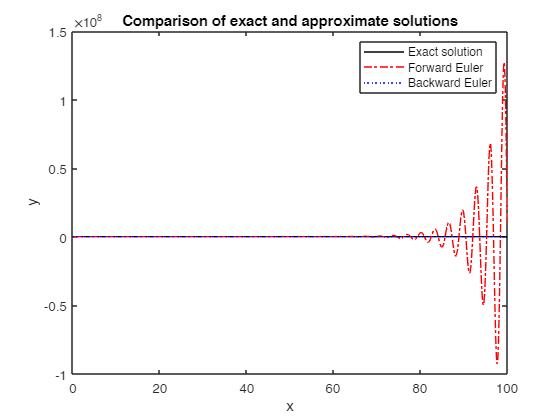


% Plot the solutions
plot(linspace(tspan(1), tspan(2), N+1), y_exact, 'k-', linspace(tspan(1), tspan(2), N+1), y_fe(1,:), 'r-.', linspace(tspan(1), tspan(2), N+1), y_be(1,:), 'b:')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')
title('Comparison of exact and approximate solutions')


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_fe);

Time taken for Forward Euler method: 9.914300 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_be);

Time taken for Backward Euler method: 2131.598900 seconds


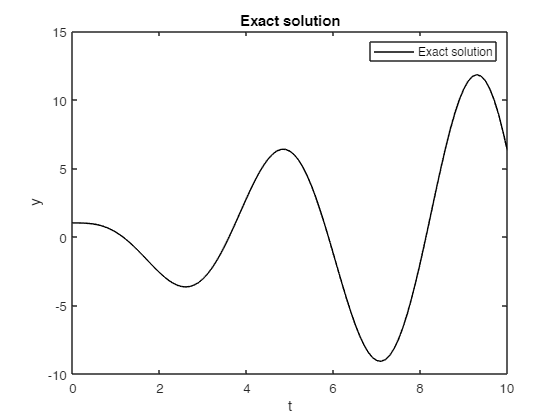

figure;
plot(linspace(tspan(1), tspan(2), N+1), y_exact, 'black-');
xlabel('t');
ylabel('y');
legend('Exact solution');
title('Exact solution');

% Fourth-order ODE: y'''' + 4y'' + 4y = 0, y(0) = 1, y'(0) = 0, y''(0) = 0, y'''(0) = -4
% Exact solution: y(t) = ((x - 1) * sin(sqrt(2) * x))/sqrt(2) + (x + 1) * cos(sqrt(2) * x)

% Define the ODE as a function handle
f = @(x, y) [y(2); y(3); y(4); -4*y(2)-4*y(3)-y(1)];

% Define the exact solution
y_exact = @(x) ((x - 1) .* sin(sqrt(2) .* x))/sqrt(2) + (x + 1) .* cos(sqrt(2) .* x);

% Define the initial conditions
x0 = 0;
y0 = [1; 0; 0; -4];

% Define the interval to solve the ODE on
x_interval = [0, 10];

% Define the step size
h = 0.01;

% Use the Forward Euler method to approximate the solution
tic
[x_forward, y_forward] = forward_euler(f, x0, y0, x_interval, h);
t_forward = toc * 1000;

% Use the Backward Euler method to approximate the solution
tic
[x_backward, y_backward] = backward_euler(f, x0, y0, x_interval, h);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

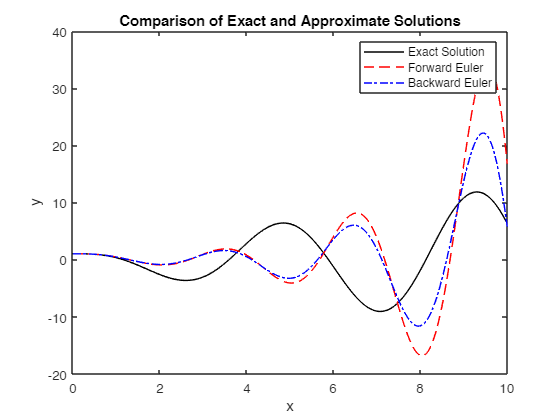

t_backward = toc * 1000;

% Compute the exact solution on the same interval with the same step size
x_exact = x_interval(1):h:x_interval(2);
y_exact_vals = y_exact(x_exact);


% Plot the results
%                                                                                                   
figure;
plot(x_exact, y_exact_vals, 'k-', x_forward, y_forward(:, 1), 'r--', x_backward, y_backward(:, 1), 'b-.');
xlabel('x');
ylabel('y');
title('Comparison of Exact and Approximate Solutions');
legend('Exact Solution', 'Forward Euler', 'Backward Euler');


% Display the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', t_forward);

Time taken for Forward Euler method: 9.128900 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', t_backward);

Time taken for Backward Euler method: 1536.467600 seconds





% Forward Euler method implementation
function [x, y] = forward_euler(f, x0, y0, x_interval, h)
    % Initialize the output arrays
    x = x_interval(1):h:x_interval(2);
    y = zeros(length(x), length(y0));
    y(1, :) = y0;
    
    % Apply the Forward Euler method
    for i = 2:length(x)
        y(i, :) = y(i-1, :) + h*f(x(i-1), y(i-1, :))';
    end
end

% Backward Euler method implementation
function [x, y] = backward_euler(f, x0, y0, x_interval, h)
    % Initialize the output arrays
    x = x_interval(1):h:x_interval(2);
    y = zeros(length(x), length(y0));
    y(1, :) = y0;
    
    % Apply the Backward Euler method
    for i = 2:length(x)
        y(i, :) = fsolve(@(z) z - y(i-1, :) - h*f(x(i), z)', y(i-1, :));
    end
end
